# `Digital signal processing Project on Speaker recognition using KNN algorithm`

`Sathvik HR`

`Varun S`

`Nikshep HG`

`Punith GV`

## `1) Preparation of Dataset and Preprocessing`


clc 
close all
clear 

dataDir = HelperAN4Download;
ads = audioDatastore(dataDir,'IncludeSubfolders',true, ...
    'FileExtensions','.flac', ...
    'LabelSource','foldernames')

ads =   audioDatastore with properties:

                       Files: {
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\an36-fejs-b.flac';
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\an37-fejs-b.flac';
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\an38-fejs-b.flac'
                               ... and 122 more
                              }
                     Folders: {
                              'C:\Users\sathv\AppData\Local\Temp\an4\wav\flacData'
                              }
                      Labels: [fejs; fejs; fejs ... and 122 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


[adsTrain, adsTest] = splitEachLabel(ads,0.8);% splitting dataset 
adsTrain

adsTrain =   audioDatastore with properties:

                       Files: {
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\an36-fejs-b.flac';
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\an37-fejs-b.flac';
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\an38-fejs-b.flac'
                               ... and 94 more
                              }
                     Folders: {
                              'C:\Users\sathv\AppData\Local\Temp\an4\wav\flacData'
                              }
                      Labels: [fejs; fejs; fejs ... and 94 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


trainDatastoreCount = countEachLabel(adsTrain)

trainDatastoreCount = 10×2 table
    Label    Count
    _____    _____

    fejs      10  
    fmjd      10  
    fsrb      10  
    ftmj      10  
    fwxs      10  
    mcen      10  
    mrcb      10  
    msjm      10  
    msjr      10  
    msmn       7  


adsTest

adsTest =   audioDatastore with properties:

                       Files: {
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\cen6-fejs-b.flac';
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\cen7-fejs-b.flac';
                              ' ...\Users\sathv\AppData\Local\Temp\an4\wav\flacData\fejs\cen8-fejs-b.flac'
                               ... and 25 more
                              }
                     Folders: {
                              'C:\Users\sathv\AppData\Local\Temp\an4\wav\flacData'
                              }
                      Labels: [fejs; fejs; fejs ... and 25 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


testDatastoreCount = countEachLabel(adsTest)

testDatastoreCount = 10×2 table
    Label    Count
    _____    _____

    fejs       3  
    fmjd       3  
    fsrb       3  
    ftmj       3  
    fwxs       2  
    mcen       3  
    mrcb       3  
    msjm       3  
    msjr       3  
    msmn       2  



[sampleTrain, dsInfo] = audioread("C:\Users\sathv\AppData\Local\Temp\an4\wav\flacData\mrcb\an101-mrcb-b.flac");%reading sample audio from dataset
sound(sampleTrain,dsInfo)
reset(adsTrain)
fs = dsInfo;
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);
 melC = mfcc(sampleTrain,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);%calculating MFCC of sample audio
 S = melSpectrogram(sampleTrain,fs);

[numBands,numFrames] = size(S);
fprintf("Number of bandpass filters in filterbank: %d\n",numBands)

Number of bandpass filters in filterbank: 32


    fprintf("Number of frames in spectrogram: %d\n",numFrames);

Number of frames in spectrogram: 348


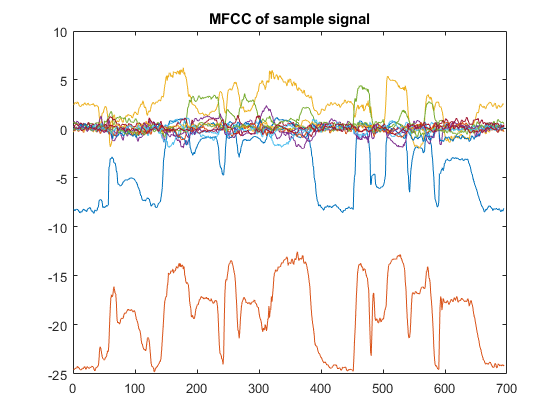

    f0 = pitch(sampleTrain,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);%calculatinng Pitch of sample audio
    plot(melC); title("MFCC of sample signal");

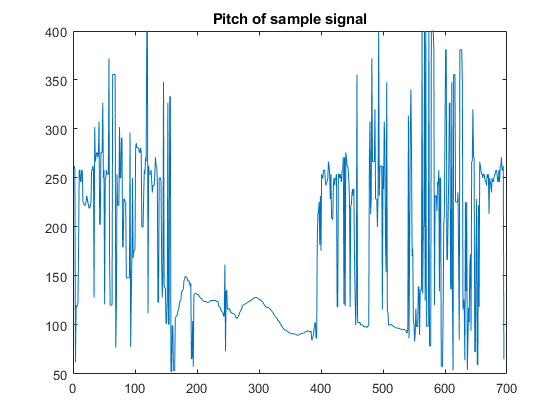

    plot(f0); title("Pitch of sample signal");

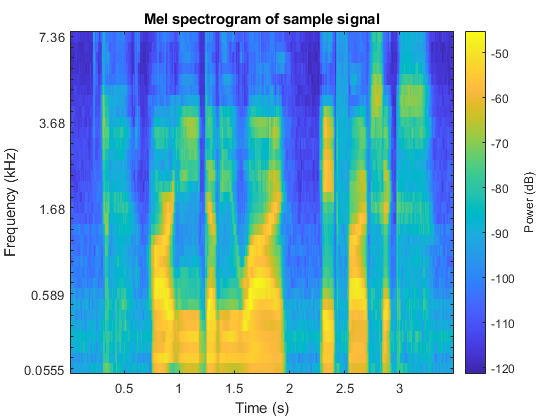

    feat = [melC,f0]; 
    melSpectrogram(sampleTrain,fs); title("Mel spectrogram of sample signal");

    reset(adsTrain)

## `2) Feature extraction of Training dataset`

    fs = dsInfo

fs = 16000

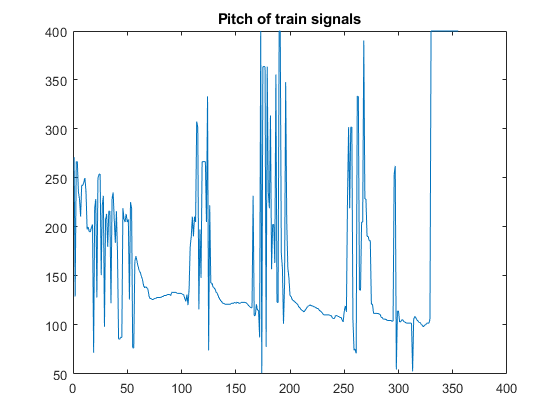

windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);

features = [];
labels = [];
while hasdata(adsTrain)
    [audioIn1,dsInfo] = read(adsTrain);
    melC1 = mfcc(audioIn1,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
     Ss = melSpectrogram(audioIn1,fs);


    
    f01 = pitch(audioIn1,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
    feat = [melC1,f01];
   
    
    
    voicedSpeech = isVoicedSpeech(audioIn1,fs,windowLength,overlapLength);
    
    feat(~voicedSpeech,:) = [];
    label = repelem(dsInfo.Label,size(feat,1));
    
    features = [features;feat];
    labels = [labels,label];
    
end
M = mean(features,1);
S1 = std(features,[],1);
features = (features-M)./S1;
plot(f01); title("Pitch of train signals");

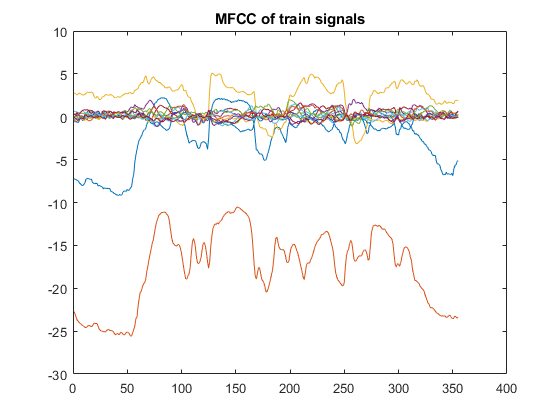

plot(melC1); title("MFCC of train signals");

[numBands,numFrames] = size(Ss);
fprintf("Number of bandpass filters in filterbank: %d\n",numBands)

Number of bandpass filters in filterbank: 32


fprintf("Number of frames in spectrogram: %d\n",numFrames);

Number of frames in spectrogram: 178


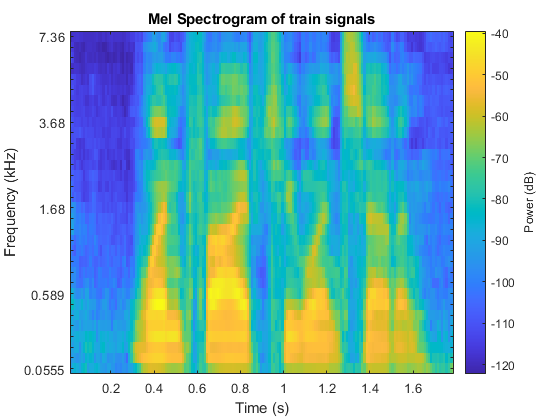

figure; melSpectrogram(audioIn1,fs); title("Mel Spectrogram of train signals");

## `3) training our KNN classification algorithm on Features Extracted`

trainedClassifier = fitcknn( ...
    features, ...
    labels, ...
    'Distance','euclidean', ...
    'NumNeighbors',5, ...
    'DistanceWeight','squaredinverse', ...
    'Standardize',false, ...
    'ClassNames',unique(labels));
trainedClassifier

trainedClassifier =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [fejs    fmjd    fsrb    ftmj    fwxs    mcen    mrcb    msjm    msjr    msmn]
           ScoreTransform: 'none'
          NumObservations: 22402
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods



k = 5;
group = labels;
c = cvpartition(group,'KFold',k); % 5-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',c);
partitionedModel

partitionedModel =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'}
           ResponseName: 'Y'
        NumObservations: 22402
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [fejs    fmjd    fsrb    ftmj    fwxs    mcen    mrcb    msjm    msjr    msmn]
         ScoreTransform: 'none'


  Properties, Methods


losses=kfoldLoss(partitionedModel)

losses = 0.0240


validationAccuracy = 1 - kfoldLoss(partitionedModel,'LossFun','ClassifError');
fprintf('\n Accuracy = %.2f%%\n', validationAccuracy*100);


 Accuracy = 97.60%


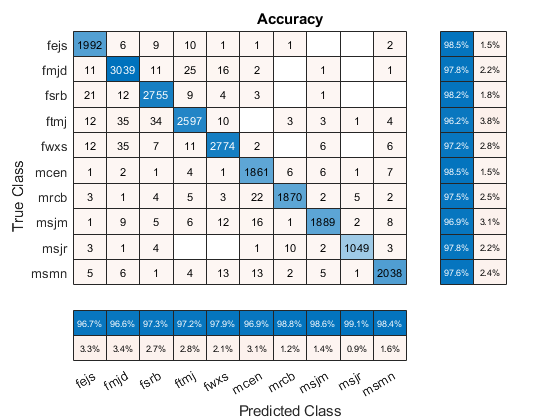


validationPredictions = kfoldPredict(partitionedModel);
figure
cm = confusionchart(labels,validationPredictions,'title','Accuracy');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

## `4) Testing`

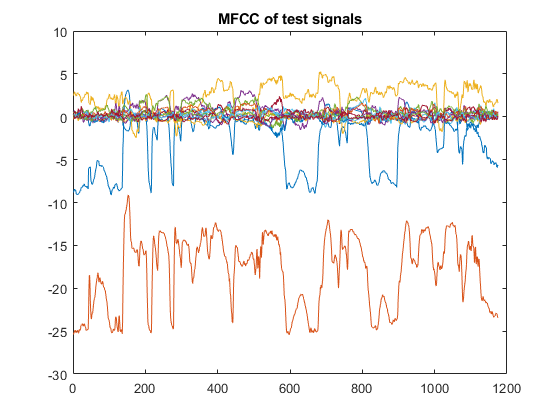



   features = [];
labels = [];
numVectorsPerFile = [];
while hasdata(adsTest)
    [audioIn2,dsInfo] = read(adsTest);
    
    melC2 = mfcc(audioIn2,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
    Sss = melSpectrogram(audioIn1,fs);
    f02 = pitch(audioIn2,fs,'WindowLength',windowLength,'OverlapLength',overlapLength);
    feat = [melC2,f02];
    
    voicedSpeech = isVoicedSpeech(audioIn2,fs,windowLength,overlapLength);
    
    feat(~voicedSpeech,:) = [];
    numVec = size(feat,1);
    
    label = repelem(dsInfo.Label,numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;feat];
    labels = [labels,label];
   
end
features = (features-M)./S1;
plot(melC2); title("MFCC of test signals");

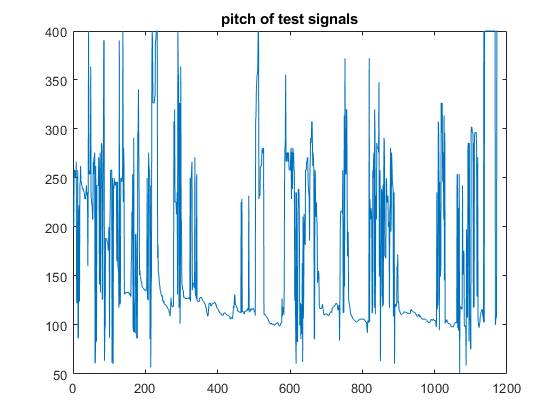

plot(f02) ;  title("pitch of test signals");

[numBands,numFrames] = size(Ss);
fprintf("Number of bandpass filters in filterbank: %d\n",numBands)

Number of bandpass filters in filterbank: 32


fprintf("Number of frames in spectrogram: %d\n",numFrames);

Number of frames in spectrogram: 178


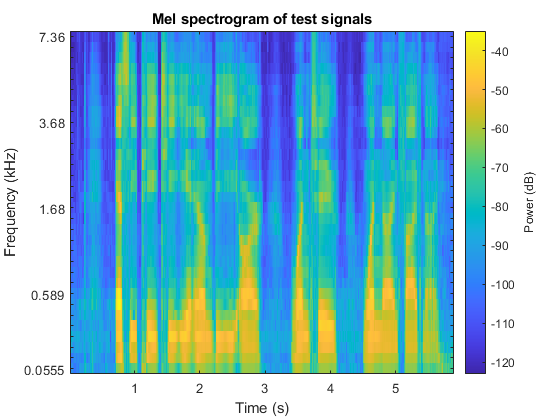

melSpectrogram(audioIn2,fs); title("Mel spectrogram of test signals");




prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));
disp(prediction);

     fmjd 
     fmjd 
     fmjd 
     fmjd 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fsrb 
     fsrb 
     fmjd 
     fsrb 
     fmjd 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fsrb 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 
     fejs 

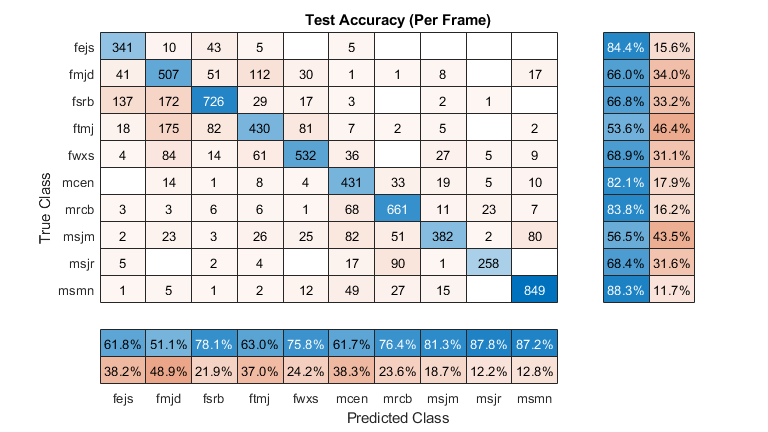


figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(labels,prediction,'title','Test Accuracy (Per Frame)');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';

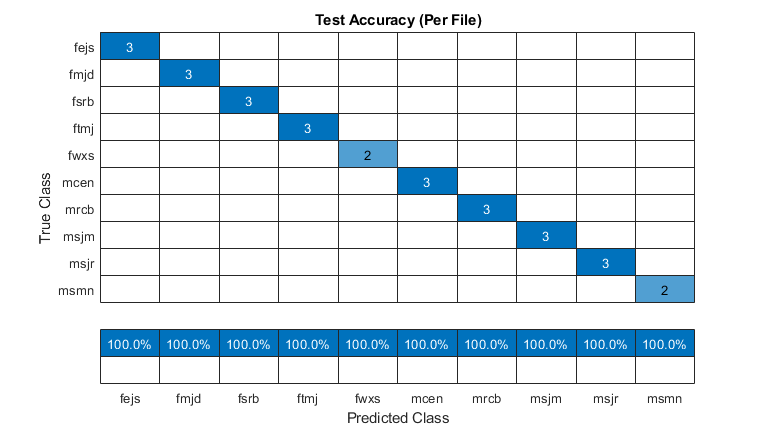


r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
cm = confusionchart(adsTest.Labels,r2,'title','Test Accuracy (Per File)');
cm.ColumnSummary = 'column-normalized';

scm.RowSummary = 'row-normalized';

    
   

## `supporting function: function to seperate voiced speech from quiet sound `

function voicedSpeech = isVoicedSpeech(x,fs,windowLength,overlapLength)
pwrThreshold = -40;
[segments,~] = buffer(x,windowLength,overlapLength,'nodelay');
pwr = pow2db(var(segments));
isSpeech = (pwr > pwrThreshold);

zcrThreshold = 1000;
zeroLoc = (x==0);
crossedZero = logical([0;diff(sign(x))]);
crossedZero(zeroLoc) = false;
[crossedZeroBuffered,~] = buffer(crossedZero,windowLength,overlapLength,'nodelay');
zcr = (sum(crossedZeroBuffered,1)*fs)/(2*windowLength);
isVoiced = (zcr < zcrThreshold);

voicedSpeech = isSpeech & isVoiced;

end






